# Tracking cantilever beam motion through marker tracking using Hough Transform

vid = VideoReader("VID1.mp4","CurrentTime",4);

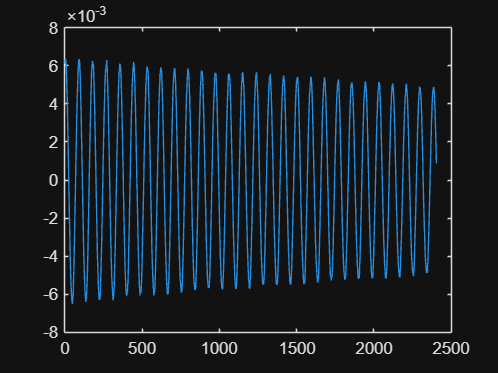

res = 2.716e-4;
disp = [];
while vid.CurrentTime < 14
    frame = readFrame(vid);
    frame = frame(460:540,1040:1155,1);
    frameEdge = edge(frame,"canny",[0.2,0.7],8);
    [center,radius] = imfindcircles(frameEdge,[10,25]);
    x = center(1)*res - res/2;
    disp = [disp,x];
    %if (size(center) ~= [1,2])
    %    imshow(frameEdge);
    %    viscircles(center,radius,'EdgeColor','g');
    %    disp(vid.CurrentTime);
    %end
end
offset = mean(disp);
disp = disp - offset;
plot(disp);

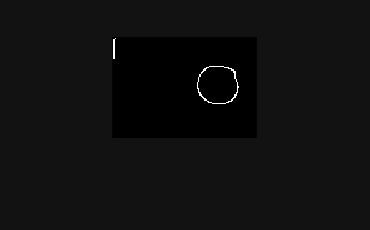

vid1 = VideoReader("VID1.mp4","CurrentTime",8.7692);
frm = readFrame(vid1);
frm = frm(460:540,1040:1155,1);
frmedge = edge(frm,'canny',[0.5,0.7],8);
imshow(frmedge);